# Rezolvarea numerică a ecuațiilor neliniare

## Ecuații în $\mathbb{R}$

**Ecuația lui Kepler** ne dă relația dintre poziția unui satelit (unghiul $E$) și timpul $t$. 


$$E-e\sin E=\frac{2\pi}{T}t.$$


$e$ este excentricitatea orbitei, iar $E$este anomalia excentrică.

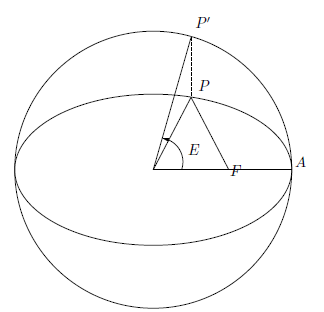

Un exemplu de valori tipice pentru un satelit este $T = 90$ de minute și $e = 0.8$. Să se determine poziția satelitului după $t = 9$ minute.  

T=90; e=0.8; t=9;
Kepler=@(E) E-e*sin(E)-2*pi*t/T;
Keplerd=@(E) 1-e*cos(E); 
E0=1;
[r1,n1]=Newton(Kepler, Keplerd, E0, 1e-9)

r1 =    1.419135783830583


n1 =      5


Rezolvare cu metoda secantei

E1=2;
[r2,n2]=secant(Kepler,E0,E1,1e-9)

r2 =    1.419135783830583


n2 =      7


## Sisteme de ecuații neliniare

Traiectoria în coordonate polare a unui satelit care se rotește pe orbită în jurul Pământului este 


$$R=\frac{C}{1+e\;\sin \left(\theta +\alpha \right)},$$


unde $(R, \theta)$ sunt coordonatele polare ale satelitului, iar $C$, $e$ și $\alpha$ sunt constante ($e$ se numește excentricitatea orbitei). Dacă satelitul a fost observat în următoarele trei poziții


$$\begin{array}{cccc}
\theta : & -{30}^{\circ }  & 0^{\circ }  & {30}^{\circ } \\
R: & 6870 & 6728 & 6615
\end{array}$$


determinați $C$, $e$ și $\alpha$. Determinați cea mai mică rază $R$ a traiectoriei și valoarea corespunzătoare a lui $\theta$.

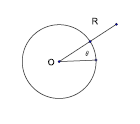

startv=[7955,0.1,5]';
[x,nit]=Newton(@sat,@jacsat,startv,1e-6);
nit

nit =      7


C=x(1); e=x(2); alpha=x(3);
C,e,alpha

C =      6.819293793207855e+03


e =    0.040598959057749


alpha =    6.623969305129950


R=@(theta) C./(1+e*sin(theta+alpha));
theta=linspace(0,2*pi,200);
[vtheta,vf,fl]=fminsearch(R,-alpha)

vtheta =   -5.053202365170787


vf =      6.553239107117241e+03


fl =      1


R(3*pi/2-alpha)

ans =      7.107865743516875e+03


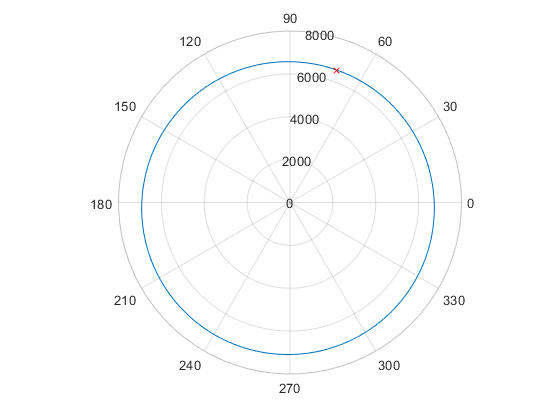

polarplot(theta,R(theta),vtheta,vf,'rx')

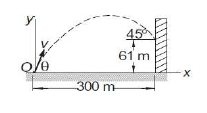

Un proiectil este lansat din $O$ cu viteza $v$ la unghiul $\theta$ cu orizontala. Ecuația parametrică a traiectoriei este


$$\begin{array}{l}
x=\left(v\;\cos \theta \right)t\\
y=-\frac{1}{2}{g\;t}^2 +\left(v\;\sin \theta \right)t\ldotp 
\end{array}$$


unde $t$ este timpul măsurat de la lansare, iar $g = 9.81m/s^2$ reprezintă accelerația gravitațională. Dacă proiectilul trebuie să atingă ținta la un unghi de $45^\circ$ (vezi figura), determinați $v$, $\theta$ și timpul de zbor.

g=9.81;
x=Newton(@proj,@projjac,[50;pi/4;5]);
v=x(1);
theta=x(2);
tz=x(3);
fprintf('viteza = %fm/s, timp= %fs\n theta = %f radiani (%f grade)\n',...
v,tz, theta,theta*180/pi)

viteza = 60.353346m/s, timp= 8.578949s
 theta = 0.952792 radiani (54.590961 grade)


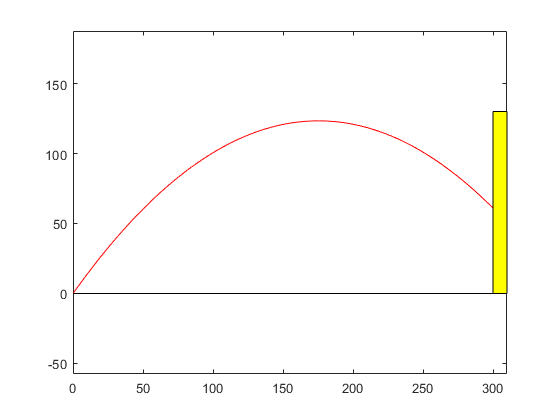

cx=@(t) v*cos(theta)*t;
cy=@(t) -g*t.^2/2+v*sin(theta)*t;
lx=cx(tz);
t=linspace(0,tz);
plot(cx(t),cy(t),'r',[0,lx+10],[0,0],'k'); hold on
fill([lx,lx+10,lx+10,lx],[0,0,130,130],'y')
axis equal
hold off

Urmează funcția și jacobianul pentru satelit

function y=sat(x)
y=[x(1)/(1-x(2)*cos(1/3*pi+x(3))) - 6870; ...
x(1)/(1+x(2)*sin(x(3))) - 6728;
x(1)/(1+x(2)*sin(1/6*pi+x(3))) - 6615];
end
function y=jacsat(x)
y=[1/(1-x(2)*sin(1/6*pi-x(3))), ...
x(1)/(1-x(2)*sin(1/6*pi-x(3)))^2*sin(1/6*pi-x(3)), ...
-x(1)/(1-x(2)*sin(1/6*pi-x(3)))^2*x(2)*sin(1/3*pi+x(3));...
1/(1+x(2)*sin(x(3))), -x(1)/(1+x(2)*sin(x(3)))^2*sin(x(3)), ...
-x(1)/(1+x(2)*sin(x(3)))^2*x(2)*cos(x(3));...
1/(1+x(2)*sin(1/6*pi+x(3))), ...
-x(1)/(1+x(2)*sin(1/6*pi+x(3)))^2*sin(1/6*pi+x(3)),...
-x(1)/(1+x(2)*sin(1/6*pi+x(3)))^2*x(2)*sin(1/3*pi-x(3))];
end

Funcția și jacobianul pentru proiectil

function y=proj(x)
g=9.81;
y=[x(1)*cos(x(2))*x(3)-300; -1/2*g*x(3)^2+x(1)*sin(x(2))*x(3)-61; ...
x(1)*cos(x(2))-g*x(3)+x(1)*sin(x(2))];
end
function y=projjac(x)
g=9.81;
y=[cos(x(2))*x(3), -x(1)*sin(x(2))*x(3), x(1)*cos(x(2)); ...
sin(x(2))*x(3), x(1)*cos(x(2))*x(3), -g*x(3)+x(1)*sin(x(2));...
cos(x(2))+sin(x(2)), -x(1)*sin(x(2))+x(1)*cos(x(2)), -g];
end